% x[n] = {2,1,-2,3,-1,-1,1}, 0<=n<=6
x = [2, 1, -2, 3, -1, -1, 1];
N = length(x);

% Compute DFT coefficients a_k = (1/N) * FFT
a = fft(x)/N;

% Display real and imaginary parts in a table
fprintf(' k    Real(a_k)        Imag(a_k)\n');

 k    Real(a_k)        Imag(a_k)


fprintf('---------------------------------\n');

---------------------------------


for k = 0:N-1
    fprintf('%2d   %+0.9f   %+0.9f\n', k, real(a(k+1)), imag(a(k+1)));
end

 0   +0.428571429   +0.000000000
 1   +0.301800667   -0.108658149
 2   +0.786406334   +0.384777456
 3   -0.302492716   -0.668791876
 4   -0.302492716   +0.668791876
 5   +0.786406334   -0.384777456
 6   +0.301800667   +0.108658149


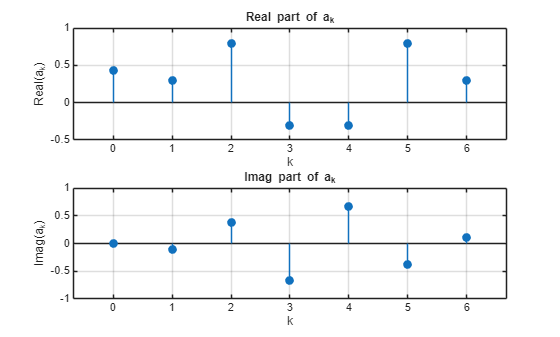


% Optional: plot real and imag (stem)
figure(1);
subplot(2,1,1);
stem(0:N-1, real(a), 'filled');
xlabel('k'); ylabel('Real(a_k)');
title('Real part of a_k');
grid on;

subplot(2,1,2);
stem(0:N-1, imag(a), 'filled');
xlabel('k'); ylabel('Imag(a_k)');
title('Imag part of a_k');
grid on;